% Parámetros iniciales
c_s0 = 0.5;
c_d0 = 0;
v_s = 92000;
v_d = 55000;
f_0 = 440;
t_0 = 0;
t_f = 500;

% Diferente número de iteraciones para runge kutta
N0 = 50;
N1 = 20;
N2 = 10;
N3 = 5;
N4 = 3;

% RESULTADOS: 

% Método análitico
C_s = @(t) 0.5*exp(-0.0047*t);
C_d = @(t) 0.7246*exp(-0.0047*t)-0.7246*exp(-0.0080*t);

% Método númerico N0
[resultado_c_s_0, resultado_c_d_0] = runge_kutta(c_s0, c_d0, v_s, v_d, f_0, t_0, t_f, N0);

% Método númerico N1
[resultado_c_s_1, resultado_c_d_1] = runge_kutta(c_s0, c_d0, v_s, v_d, f_0, t_0, t_f, N1);

% Método númerico N2
[resultado_c_s_2, resultado_c_d_2] = runge_kutta(c_s0, c_d0, v_s, v_d, f_0, t_0, t_f, N2);

% Método númerico N3
[resultado_c_s_3, resultado_c_d_3] = runge_kutta(c_s0, c_d0, v_s, v_d, f_0, t_0, t_f, N3);

% Método númerico N4
[resultado_c_s_4, resultado_c_d_4] = runge_kutta(c_s0, c_d0, v_s, v_d, f_0, t_0, t_f, N4);


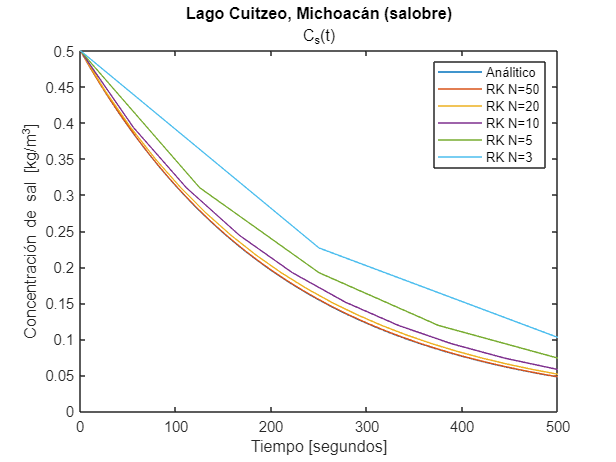

% Plot método númerico C_s(t)

t = 0:0.1:500;
plot(t, C_s(t))
title("Lago Cuitzeo, Michoacán (salobre)")
subtitle("C_s(t)")
ylabel("Concentración de sal [kg/m^3]")
xlabel("Tiempo [segundos]")

hold on

% Plot método runge kutta N0
t0 = linspace(t_0,t_f,N0);
plot(t0, resultado_c_s_0);

% Plot método runge kutta N1
t1 = linspace(t_0,t_f,N1);
plot(t1, resultado_c_s_1);

% Plot método runge kutta N2
t2 = linspace(t_0,t_f,N2);
plot(t2, resultado_c_s_2);

% Plot método runge kutta N3
t3 = linspace(t_0,t_f,N3);
plot(t3, resultado_c_s_3);

% Plot método runge kutta N4
t4 = linspace(t_0,t_f,N4);
plot(t4, resultado_c_s_4);

legend("Análitico", "RK N=50", "RK N=20", "RK N=10", "RK N=5", "RK N=3")

hold off

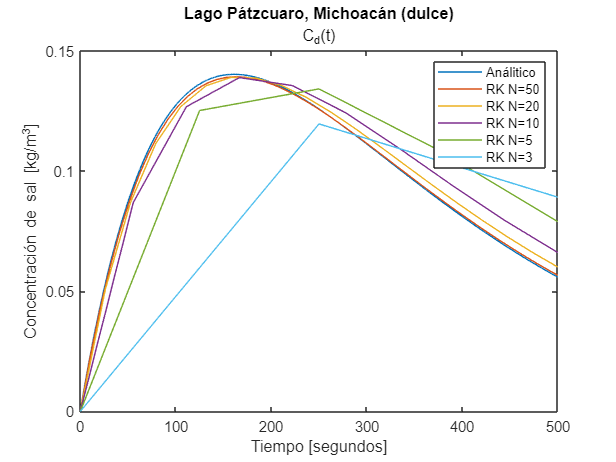


% Plot método númerico C_d(t)
plot(t, C_d(t))
title("Lago Pátzcuaro, Michoacán (dulce)")
subtitle("C_d(t)")
ylabel("Concentración de sal [kg/m^3]")
xlabel("Tiempo [segundos]")

hold on

% Plot método runge kutta N0
t0 = linspace(t_0,t_f,N0);
plot(t0, resultado_c_d_0);

% Plot método runge kutta N1
t1 = linspace(t_0,t_f,N1);
plot(t1, resultado_c_d_1);

% Plot método runge kutta N2
t2 = linspace(t_0,t_f,N2);
plot(t2, resultado_c_d_2);

% Plot método runge kutta N3
t3 = linspace(t_0,t_f,N3);
plot(t3, resultado_c_d_3);

% Plot método runge kutta N4
t4 = linspace(t_0,t_f,N4);
plot(t4, resultado_c_d_4);

legend("Análitico", "RK N=50", "RK N=20", "RK N=10", "RK N=5", "RK N=3")